clear all; close all
%load("measurement_psd.mat")
load("measurement_psd_v2.mat")

e = measurement_PSD;
rms(e)*1e3

ans = 279.1706


%removing useless data 
N_trash = 1500; 
e =e(N_trash:end)

e =    -0.0700
         0
   -0.0682
         0
   -0.0672
         0
   -0.0660
         0
   -0.0649
         0


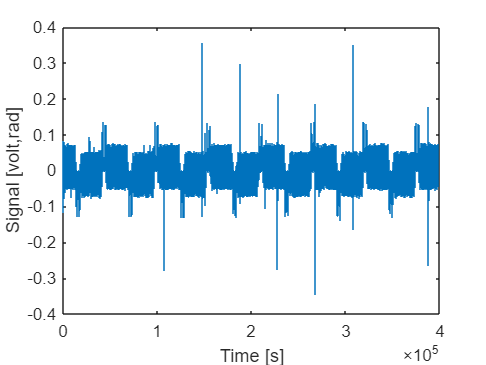


% Plot the measurement
figure(); clf();
stairs(e);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010



%window settings
min_freq = 0.05; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize) %window size in data points 

nfft = 80000

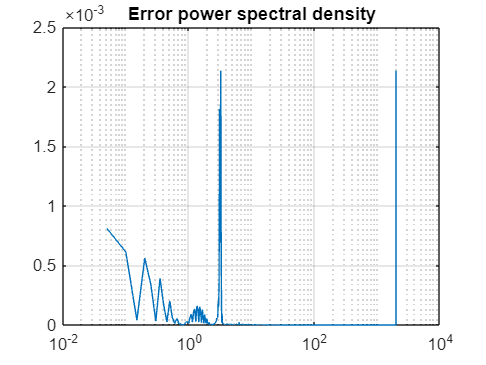

n_overlap = round(nfft/3);

%Tf estimate
[psd_e, F] = pwelch(e,hann(nfft),n_overlap,nfft,fs,'psd'); %spectral power disturbance

figure()
semilogx(F,(abs(psd_e)))
title("Error power spectral density")
grid on; hold off


N = length(e);
xdft = fft(e);
xdft = xdft(1:N/2+1);

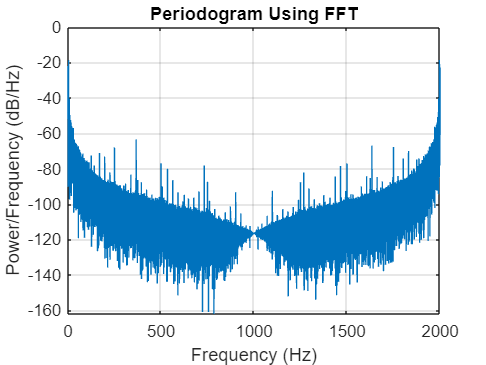

psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(e):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")